# Wood Knots Detection Project

Use this script to complete the wood knots detection project. Follow along with each step and return to Coursera to answer quiz questions when prompted.

#### Loading the Ground Truth Data

The ground truth for the training images in the wood knots dataset is stored in a ".mat" file in the course files. To access the ground truth data, you'll need to load it and then update the image file locations to match your system. To do this, run the following section of code.

load WoodKnotsGroundTruth

Overwrite the image file locations stored in the ground truth variable to match your system.

testPath = overwriteGTruthLocations(gTruthTrain);

## Step 1: Prepare the Dataset

First, familiarize yourself with the wood knots dataset.

- Run the line below to load the training images and ground truth labels into the Image Labeler app.

- Then review the ground truth bounding boxes to guide you for the next task. Note how bounding boxes are drawn relatively tight around the knots, with minimal extra area included.

imageLabeler(gTruthTrain)

The course files also include 10 test images that have not been labeled. You'll need to create the ground truth for these images so you can evaluate your trained model later.

- Run the line below to load the unlabeled test images into the Image Labeler app.

- Use the Image Labeler app to create the ground truth labels for the knots. Make sure to match the training images for how bounding boxes are drawn around knots. Some examples of correct and incorrect labeling are shown here: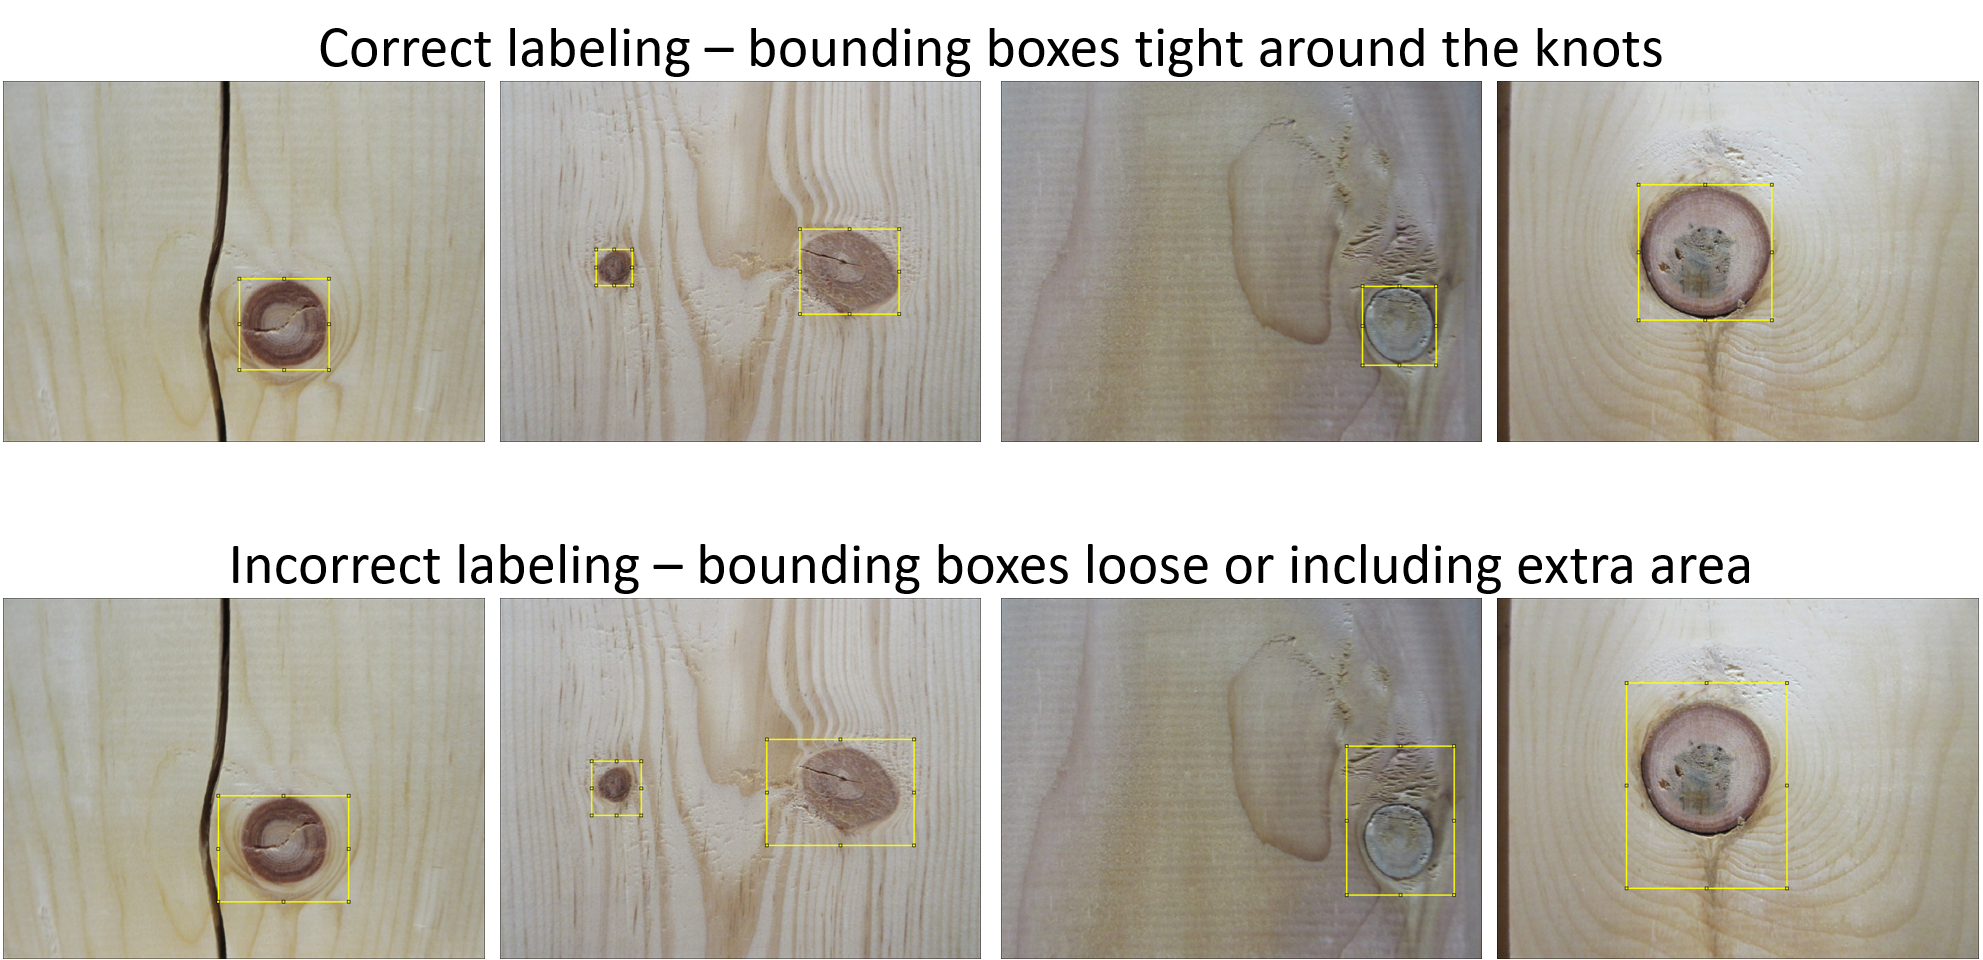

- Export the ground truth as a mat file named `WoodKnotsGroundTruthTest.mat`.

imageLabeler(testPath)

To evaluate your detector's performance later, you'll need to compare its results to this test set ground truth.

- Run the code below to load the ground truth you just saved into your MATLAB workspace.

- If you get an error here, make sure the ".mat" file is named correctly and is located in the MATLAB search path.

load WoodKnotsGroundTruthTest.mat

You'll also need to load the test images as an image datastore before running them through your trained detector.

imdsTest = imageDatastore(testPath);

Well done! Before proceeding to the next step:

- Take the quiz "Project: Wood Knots Detection Step 1".

## Step 2: Train and Evaluate a Detector

Next you'll use the training ground truth we've provided, `gTruthTrain`, to train an ACF object detector.

- Fill in and run the code to train the detector here.

- Use the default settings for the ACF detector.

- If you need help, you can reference the script `ObjectDetectionWithML.mlx`.

% Fill in your code here



Now that your detector is trained, use it to detect the wood knots on the test set.

- Fill in and run the code to apply the detector using the default settings of the `detect` function.

- Remember, the `detect` function can accept the test datastore variable, `imdsTest`, to run on all the images in the datastore.

% Fill in your code here



Finally, visualize your detection results and calculate the detection metrics miss rate.

- Fill in and run the code to do this here.

- Remember, if you need help, you can reference the script `ObjectDetectionWithML.mlx`

% Fill in your code here



You should see results that could use some improvement. Don't worry; you'll fix those soon.

- Take the quiz "Project: Wood Knots Detection Step 2".

## Step 3: Improving the Detections

Now that you have a trained detector, your next step is to improve it.

- Based on the last question in the quiz "Project: Wood Knots Detection Step 2", modify the [`detect`](https://www.mathworks.com/help/vision/ref/acfobjectdetector.detect.html#mw_68d295a2-8440-43f0-9791-8e41c2c8eaf4) function to capture the missing detection. Specifically, lower the `"threshold"` value below the default of -1.

- Fill in and run the code here to again: visualize your detection results and calculate the detection miss rate.

% Fill in your code here



- Take the quiz "Project: Wood Knots Detection Step 3".

## Extra Credit: Removing Redundant Detections

Use this last section to modify your detection results. See if you can merge the overlapping, redundant detections. Hint: use the `selectStrongestBbox` function. You can find [the documentation page for this function here](https://www.mathworks.com/help/vision/ref/selectstrongestbbox.html).

% Fill in your code here




#### Helper Function

This function overwrites the image file locations stored in the ground truth variable to match your system.

function testPath = overwriteGTruthLocations(gTruthTrain)
% Find the location of the image files
trainPath = fileparts(which("IMG_3177.JPG"));
if isempty(trainPath)
    error("The course files are not on the MATLAB search path." + ...
        "Follow the instructions when downloading the course " + ...
        "files to add them to your path.")
end

% Overwrite locations for images
currentPath = string(fileparts(gTruthTrain.DataSource.Source{1}));
changeFilePaths(gTruthTrain,[currentPath, trainPath]);

% Save the test path
testPath = erase(trainPath,'Train') + "Test";
end

*Copyright 2022 The MathWorks, Inc.*